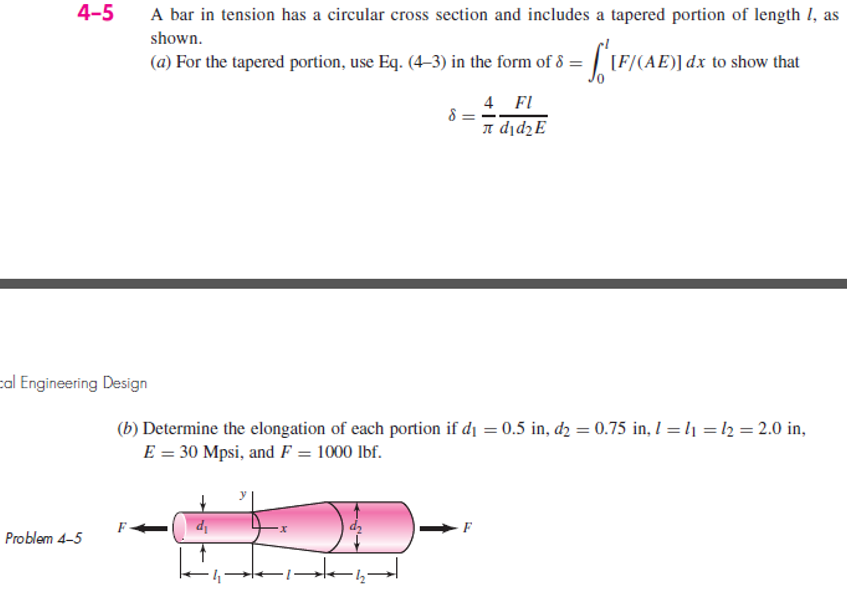

# assumptions

old_assum = assumptions;
clearassum;

# given

u = symunit;
F = sym('F', 'positive');
L = sym('L', 'positive');
D = sym('D', [1 2], 'positive');
E = sym('E', 'positive');
x = sym('x');

# elongation formula

Dfun = findpoly(1, 'thru', [0 D(1)], [L D(2)]);
Afun = sympi*Dfun^2/4;
deltafun([F L D E]) = int(F/(Afun*E), [0 L])

$$deltafun(F, L, D1, D2, E) = \frac{4\,F\,L}{D_{1}\,D_{2}\,\text{E}\,\pi }$$

# elongation of each bar portion

args = {1000*u.lbf, 2.0*u.in, [0.5; 0.5; 0.75]*u.in, [0.5; 0.75; 0.75]*u.in, 30e6*u.psi};
delta = simplify(deltafun(args{:}));
delta_vpa = vpa(delta, 3) %#ok

$$delta\_vpa = \left(\begin{array}{c} 3.4\,10^{-4}\,\mathrm{in}\\ 2.26\,10^{-4}\,\mathrm{in}\\ 1.51\,10^{-4}\,\mathrm{in} \end{array}\right)$$

clear delta_vpa;
setassum(old_assum, 'clear');